# NR Channel Estimation Using CSI-RS

Helper functions

function plotGrid(gridSize,csirsInd,csirsSym)
%    plotGrid(GRIDSIZE,CSIRSIND,CSIRSSYM) plots the carrier grid of size GRIDSIZE
%    by populating the grid with CSI-RS symbols using CSIRSIND and CSIRSSYM.

    figure()
    cmap = colormap(gcf);
    chpval = {20,2};
    chpscale = 0.25*length(cmap); % Scaling factor

    tempSym = csirsSym;
    tempSym(tempSym ~= 0) = chpval{1}; % Replacing non-zero-power symbols
    tempSym(tempSym == 0) = chpval{2}; % Replacing zero-power symbols
    tempGrid = complex(zeros(gridSize));
    tempGrid(csirsInd) = tempSym;

    image(chpscale*tempGrid(:,:,1)); % Multiplied with scaling factor for better visualization
    axis xy;
    names = {'NZP CSI-RS','ZP CSI-RS'};
    clevels = chpscale*[chpval{:}];
    N = length(clevels);
    L = line(ones(N),ones(N),'LineWidth',8); % Generate lines
    % Index the color map and associate the selected colors with the lines
    set(L,{'color'},mat2cell(cmap( min(1+clevels,length(cmap) ),:),ones(1,N),3)); % Set the colors according to cmap
    % Create legend 
    legend(names{:});

    title('Carrier Grid Containing CSI-RS')
    xlabel('OFDM Symbols');
    ylabel('Subcarriers');
end

Carrier configuration: 25*12 = 300

carrier = nrCarrierConfig;
carrier.NSizeGrid = 25;
carrier.SubcarrierSpacing = 15;
carrier.NSlot = 1;
carrier.NFrame = 0;

CSI-RS configuration:

csirs = nrCSIRSConfig;
csirs.CSIRSType = {'nzp','zp'};
csirs.CSIRSPeriod = {[5 1],[5 1]};
csirs.Density = {'one','one'};
csirs.RowNumber = [3 5];
csirs.SymbolLocations = {1,6};
csirs.SubcarrierLocations = {6,4};
csirs.NumRB = 25;

powerCSIRS = 0;
disp(['CSI-RS power scaling: ' num2str(powerCSIRS) ' dB']);

CSI-RS power scaling: 0 dB


sym = nrCSIRS(carrier,csirs);
mag = db2mag(powerCSIRS);
disp(['mag = ' num2str(mag)]);

mag = 1


csirsSym = sym*db2mag(powerCSIRS);

csirsInd = nrCSIRSIndices(carrier,csirs);

ports = max(csirs.NumCSIRSPorts);   % Number of antenna ports
txGrid = nrResourceGrid(carrier,ports);

txGrid(csirsInd) = csirsSym;

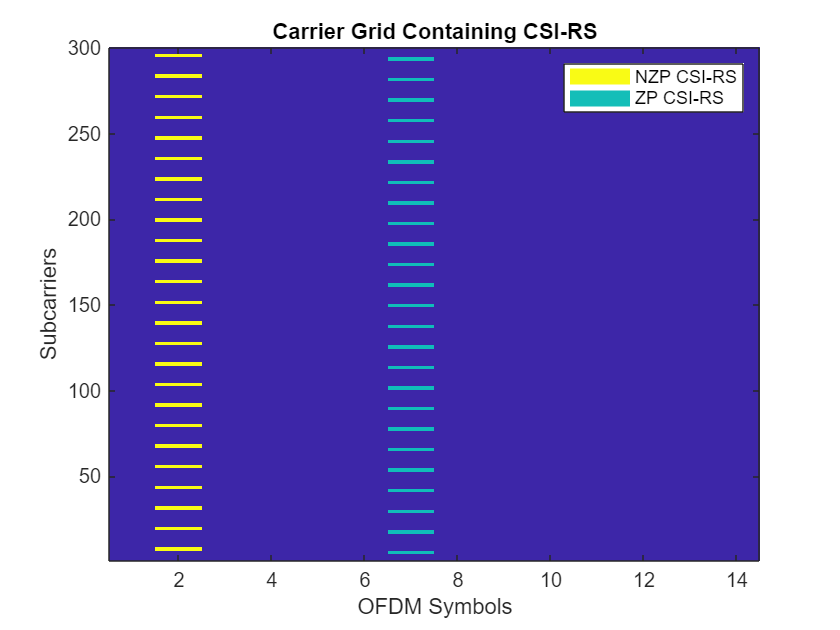

plotGrid(size(txGrid),csirsInd,csirsSym);

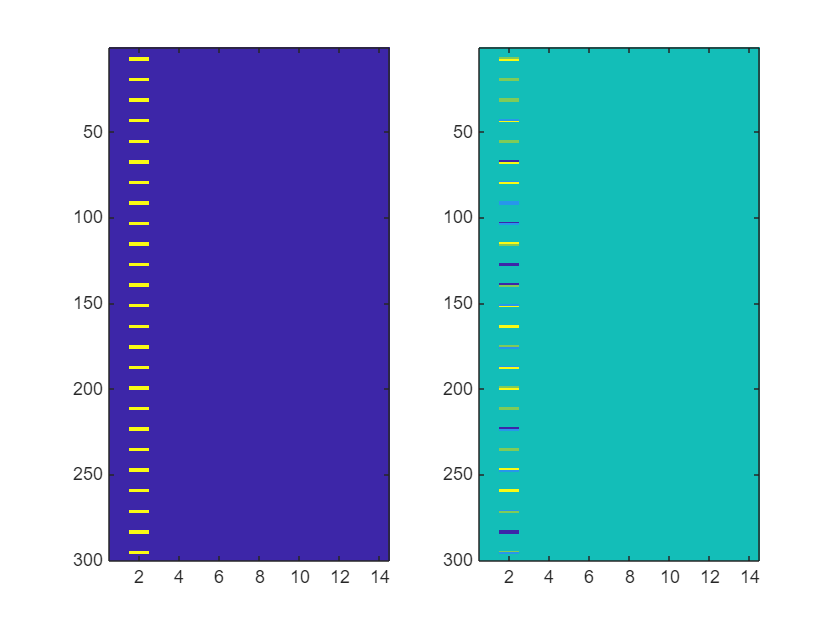

figure;
subplot(1,2,1)
imagesc(abs(txGrid(:,:,1)));
subplot(1,2,2)
imagesc(angle(txGrid(:,:,1)))

300*14 = 4200

[txWaveform,ofdmInfo] = nrOFDMModulate(carrier,txGrid);

R = 4;

channel = nrTDLChannel;
channel.NumTransmitAntennas = ports;
channel.NumReceiveAntennas = R;
channel.DelayProfile = 'TDL-C';
channel.MaximumDopplerShift = 10;
channel.DelaySpread = 1e-8;

waveformInfo = nrOFDMInfo(carrier);
channel.SampleRate = waveformInfo.SampleRate

channel =   nrTDLChannel with properties:

                 DelayProfile: 'TDL-C'
                  DelaySpread: 1.0000e-08
          MaximumDopplerShift: 10
                   SampleRate: 7680000
              MIMOCorrelation: 'Low'
                 Polarization: 'Co-Polar'
        TransmissionDirection: 'Downlink'
          NumTransmitAntennas: 4
           NumReceiveAntennas: 4
           NormalizePathGains: true
                  InitialTime: 0
                 NumSinusoids: 48
                 RandomStream: 'mt19937ar with seed'
                         Seed: 73
      NormalizeChannelOutputs: true
             ChannelFiltering: true
    TransmitAndReceiveSwapped: false


chInfo = info(channel);
maxChDelay = chInfo.MaximumChannelDelay;
txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))];

[rxWaveform,pathGains] = channel(txWaveform);

pathFilters = getPathFilters(channel);
H_actual = nrPerfectChannelEstimate(carrier,pathGains,pathFilters);

SNRdB = 100;           % in dB
SNR = 10^(SNRdB/10);  % Linear value
N0 = 1/sqrt(2.0*R*double(ofdmInfo.Nfft)*SNR); % Noise variance
rng(0);
noise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
% rxWaveform = rxWaveform + noise;

% Disable ZP-CSI-RS resource, not going to be used for timing and channel
% estimation
csirs.CSIRSPeriod = {[5 1],'off'};
% Generate reference symbols and apply power scaling
refSym = db2mag(powerCSIRS)*nrCSIRS(carrier,csirs);
% Generate reference indices
refInd = nrCSIRSIndices(carrier,csirs);
offset = nrTimingEstimate(carrier,rxWaveform,refInd,refSym)

offset = 7

rxWaveform = rxWaveform(1+offset:end,:);

rxGrid = nrOFDMDemodulate(carrier,rxWaveform); % Of size K-by-L-by-R

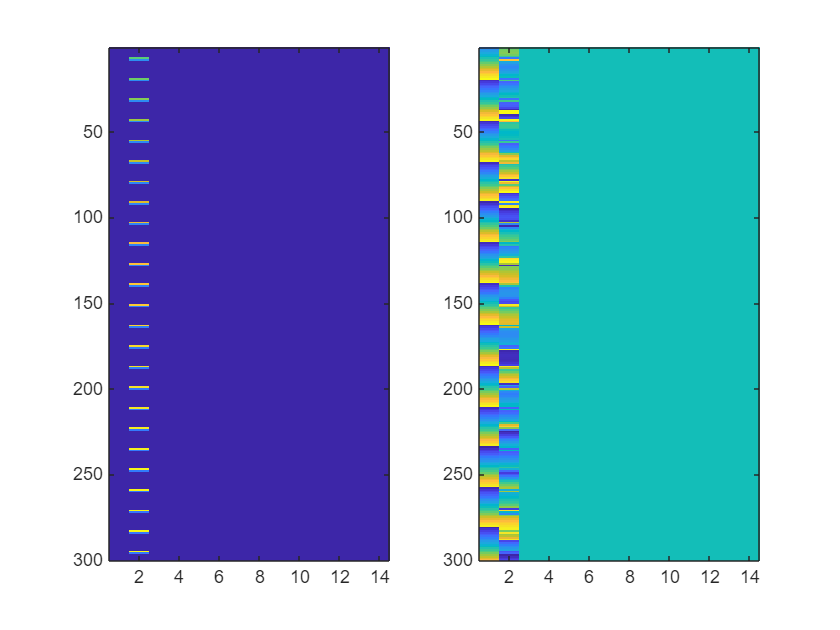

figure;
subplot(1,2,1);
imagesc(abs(rxGrid(:,:,1)));
subplot(1,2,2);
imagesc(angle(rxGrid(:,:,1)));

cdmLen = [2 1]; % Corresponds to CDMType = 'FD-CDM2'
[H_est,nVar] = nrChannelEstimate(rxGrid,refInd,refSym);
disp(['Estimated noise variance = ' num2str(nVar)])

Estimated noise variance = 0.86117


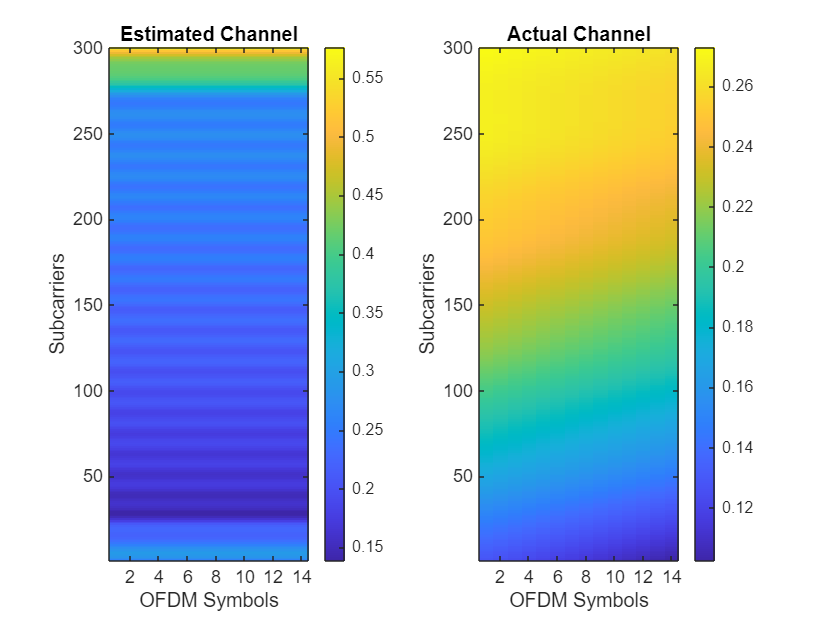

figure;

% Plot the estimated channel
subplot(1,2,1);
imagesc(abs(H_est(:,:,1,1)));
colorbar;
title('Estimated Channel');
axis xy;
xlabel('OFDM Symbols');
ylabel('Subcarriers');

% Plot the actual channel
subplot(1,2,2);
imagesc(abs(H_actual(:,:,1,1)));
colorbar;
title('Actual Channel');
axis xy;
xlabel('OFDM Symbols');
ylabel('Subcarriers');

H_err = (H_est - H_actual(:,:,:,1:size(H_est,4)));
[minErr,maxErr] = bounds(abs(H_err),'all');
disp(['Absolute value of the channel estimation error is in the range of [' num2str(minErr) ', ' num2str(maxErr) ']'])

Absolute value of the channel estimation error is in the range of [4.6139e-05, 1.1919]


rxGrid_calucated = zeros(300, 14, 4);
% Loop over subcarriers and symbols
for i = 1:300 % Subcarriers
    for j = 1:14 % Symbols
        % H_est(i,j,:,:) is 4-by-4, txGrid(i,j,:) is 4-by-1
        H = squeeze(H_actual(i,j,:,:));
        tx = squeeze(txGrid(i,j,:));
        rxGrid_calucated(i,j,:) = H * tx;
    end
end

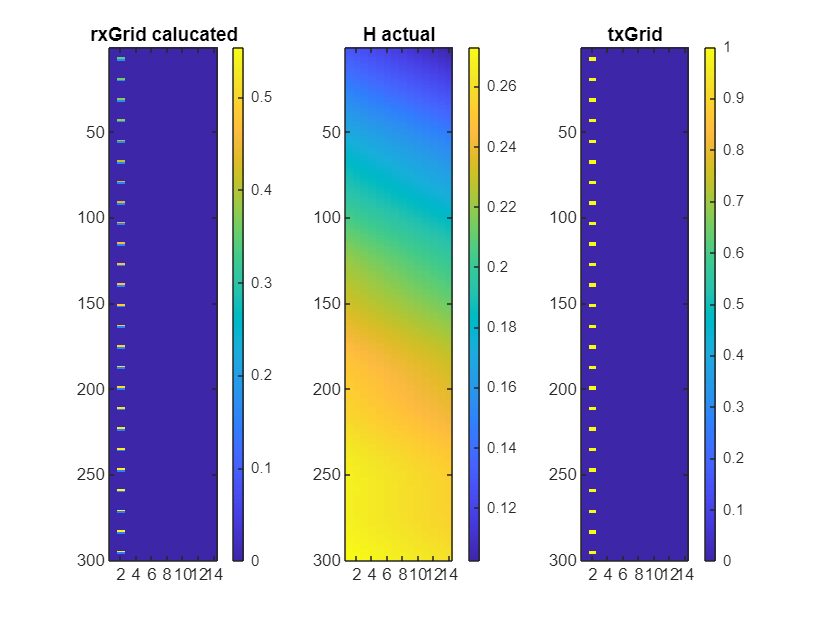

figure;
subplot(1,3,1)
imagesc(abs(rxGrid_calucated(:,:,1)));
colorbar;
title('rxGrid calucated')
subplot(1,3,2)
imagesc(abs(H_actual(:,:,1)));
colorbar;
title('H actual')
subplot(1,3,3)
imagesc(abs(txGrid(:,:,1)));
colorbar;
title('txGrid')

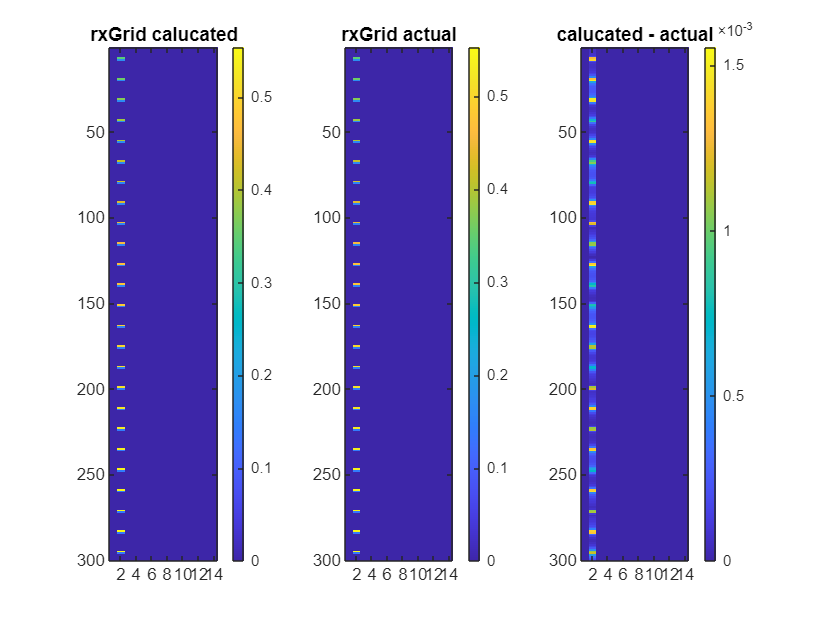

figure;
subplot(1,3,1)
imagesc(abs(rxGrid_calucated(:,:,1)));
title('rxGrid calucated')
colorbar;
subplot(1,3,2)
imagesc(abs(rxGrid(:,:,1)));
title('rxGrid actual')
colorbar;
subplot(1,3,3)
imagesc(abs(rxGrid_actual(:,:,1) - rxGrid(:,:,1)));
title('calucated - actual')
colorbar;

% rxGrid_calucated_h_est = zeros(300, 14, 4);
% % Loop over subcarriers and symbols
% for i = 1:300 % Subcarriers
%     for j = 1:14 % Symbols
%         % H_est(i,j,:,:) is 4-by-4, txGrid(i,j,:) is 4-by-1
%         H = squeeze(H_est(i,j,:,:));
%         tx = squeeze(txGrid(i,j,:));
%         rxGrid_calucated_h_est(i,j,:) = H * tx;
%     end
% end

% figure;
% subplot(1,3,1)
% imagesc(abs(rxGrid_calucated(:,:,1)));
% colorbar;
% title('rxGrid calucated')
% subplot(1,3,2)
% imagesc(abs(H_actual(:,:,1)));
% colorbar;
% title('H actual')
% subplot(1,3,3)
% imagesc(abs(txGrid(:,:,1)));
% colorbar;
% title('txGrid')